# Example 6.11: Applying a Derivative Filter to a Signal

Note: this script reproduces Example 6.11 (Section 6.3.1) of **Statistics for Chemical Engineers**: convolution of a cdf with a derivative filter. Victor Z UW-Madison, 2019 derivative filter

clc;  clear all; close all hidden; format short;

## Derivative filter

generate derivative filter coefficients

w=[1,0,-1];

## Signal

generate signal

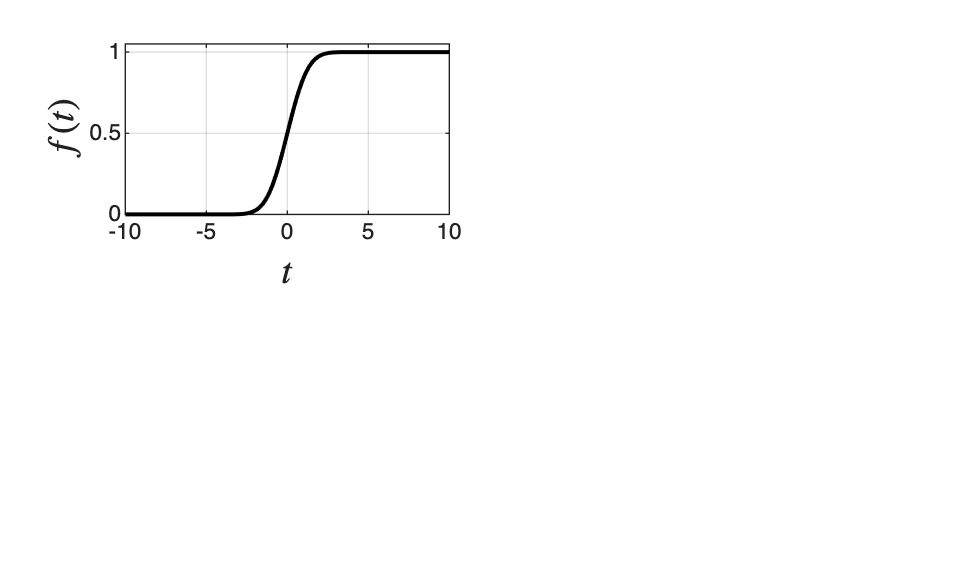

N=100;
t=linspace(-10,10,N);
f = normcdf(t);

subplot(2,2,1)
plot(t,f,'black','LineWidth',1.5)
grid on
axis([-10 10 0 1.05])
ylabel('$f(t)$','Interpreter','Latex','FontSize',14)
xlabel('$t$','Interpreter','Latex','FontSize',14)

## Convolution

perform convolution

phi=conv(f,w,'same')

phi =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0003    0.0007    0.0013    0.0023    0.0041    0.0069    0.0112    0.0174    0.0260    0.0374    0.0516    0.0684    0.0871    0.1065    0.1251    0.1412    0.1530    0.1593


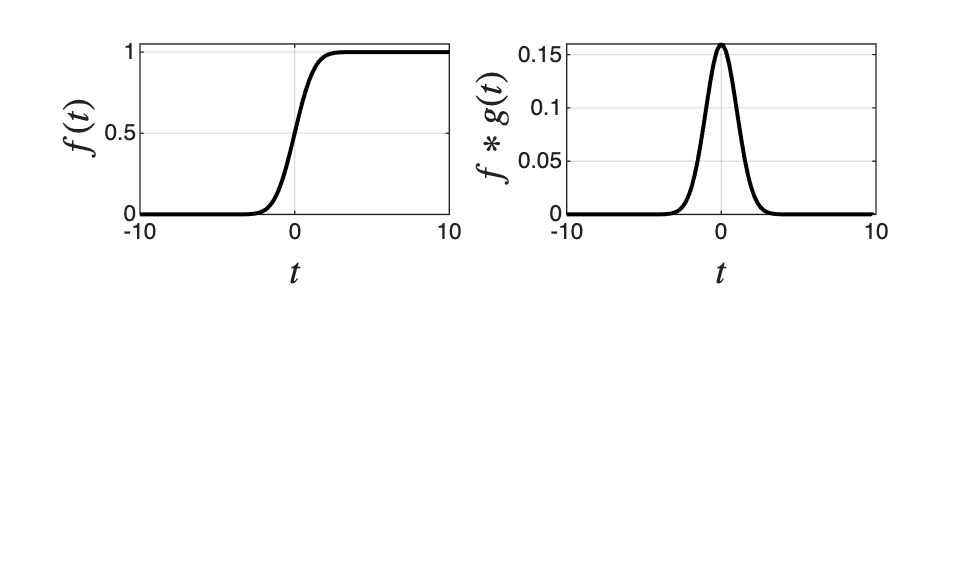


subplot(2,2,2)
plot(t,phi,'black','LineWidth',1.5)
axis([-10 10 0 0.16])
grid on
ylabel('$f*g(t)$','Interpreter','Latex','FontSize',14)
xlabel('$t$','Interpreter','Latex','FontSize',14)

print -depsc ch6_pdf_derivative_filter.eps

## Note

As in the book, the convolution shows where the cdf grows fast, slowly, or not at all: convolution highlights features of a signal.